# Code Run Test ENS 336 Project 

syms x

% Initialize ordinary dice generating function
OD = x^6 + x^5 + x^4 +x^3 + x^2 + x^1;

% Find new dice generating function
n = 20;
[D1,D2] = findDice(OD,n)

$$D1 = x^{6}+x^{4}+x^{2}$$

$$D2 = x^{6}+2\,x^{5}+2\,x^{4}+2\,x^{3}+2\,x^{2}+2\,x+1$$


% Obtain coefficient and exponents of each die
[CoeffsOD,ExpOD,ExpandedExpOD] = getCoeffsAndExponents(OD)

CoeffsOD =      1     1     1     1     1     1     0


ExpOD =      6     5     4     3     2     1


ExpandedExpOD =      6     5     4     3     2     1


[CoeffsD1,ExpD1,ExpandedExpD1] = getCoeffsAndExponents(D1)

CoeffsD1 =      1     0     1     0     1     0     0


ExpD1 =      6     4     2


ExpandedExpD1 =      6     4     2


[CoeffsD2,ExpD2,ExpandedExpD2] = getCoeffsAndExponents(D2)

CoeffsD2 =      1     2     2     2     2     2     1


ExpD2 =      6     5     4     3     2     1     0


ExpandedExpD2 =      6     5     5     4     4     3     3     2     2     1     1     0


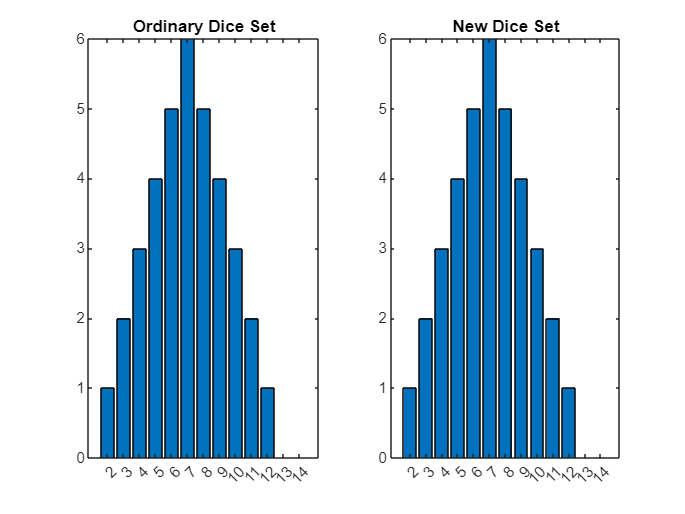


% Compare Convolution Graph
compareGraph(CoeffsOD,CoeffsD1,CoeffsD2)


% Compare Summation Table
compareTable(ExpandedExpOD,ExpandedExpD1,ExpandedExpD2)

Sum Table of Ordinary Dice:
    12    11    10     9     8     7
    11    10     9     8     7     6
    10     9     8     7     6     5
     9     8     7     6     5     4
     8     7     6     5     4     3
     7     6     5     4     3     2

Sum Table of New Dice:
    12    11    11    10    10     9     9     8     8     7     7     6
    10     9     9     8     8     7     7     6     6     5     5     4
     8     7     7     6     6     5     5     4     4     3     3     2

The sum distributions are the same.



% Compare Generating Function
[GF1,GF2] = compareGeneratingFunction(CoeffsOD,CoeffsD1,CoeffsD2)

The generating function is equal


$$GF1 = x^{12}+2\,x^{11}+3\,x^{10}+4\,x^{9}+5\,x^{8}+6\,x^{7}+5\,x^{6}+4\,x^{5}+3\,x^{4}+2\,x^{3}+x^{2}$$

$$GF2 = x^{12}+2\,x^{11}+3\,x^{10}+4\,x^{9}+5\,x^{8}+6\,x^{7}+5\,x^{6}+4\,x^{5}+3\,x^{4}+2\,x^{3}+x^{2}$$


% Test Race Game
Game(ExpandedExpOD,ExpandedExpD1,ExpandedExpD2)

.......S...R........................................................................................................................................................................
................S...................................................................................................................................................................
......................S.....R.......................................................................................................................................................
.............................S.......R..............................................................................................................................................
...............................S..............R.....................................................................................................................................
.................................S.................R...........................................

function [ODODGeneratingFunction,D1D2GeneratingFunction] = compareGeneratingFunction(OD,D1,D2)

% Obtain symbolic equation from polynomial input 
a = poly2sym(OD);
b = poly2sym(D1);
c = poly2sym(D2);
ODODGeneratingFunction = expand(a * a);
D1D2GeneratingFunction = expand(b * c);

% Compare if they are equal and display msg
if isequal(ODODGeneratingFunction, D1D2GeneratingFunction)
    disp('The generating function is equal');
else
    disp('The generating function is different.');
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function Game(OD,sichermanDie1,sichermanDie2)

% Initial race parameters
regularDicePosition = 1;
sichermanDicePosition = 1;
targetPosition = 180;

% Main game loop
while regularDicePosition < targetPosition && sichermanDicePosition < targetPosition
    
    % Rolling regular dice
    regularDiceRoll1 = randi(length(OD));
    regularDiceRoll2 = randi(length(OD));
    regularDicePosition = regularDicePosition + regularDiceRoll1 + regularDiceRoll2;
    
    % Rolling new ("Sicherman") dice
    sichermanDieIndex1 = randi(length(sichermanDie1));
    sichermanDiceRoll1 = sichermanDie1(sichermanDieIndex1);
    sichermanDieIndex2 = randi(length(sichermanDie2));
    sichermanDiceRoll2 = sichermanDie2(sichermanDieIndex2);
    sichermanDicePosition = sichermanDicePosition + sichermanDiceRoll1 + sichermanDiceRoll2;
    
    % Update race with repmat creating a sequence of '.' based on 1 row and
    % targetPosition columns
    race = repmat('.', 1, targetPosition);

    % Update the sequence of '.' and change one of them with current position of R and S
    race(1, regularDicePosition) = 'R';
    race(1, sichermanDicePosition) = 'S';
    
    % Display race by each dice rool
    clc;
    disp(race);
    
    % Pause for visualization
    pause(0.25);
end

% Determine winner
if regularDicePosition >= targetPosition && sichermanDicePosition >= targetPosition
    disp('It''s a tie!');
elseif regularDicePosition >= targetPosition
    disp('Regular dice wins!');
else
    disp('Sicherman dice wins!');
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
function compareGraph(ordinaryDie, D1, D2)

    % Conv computations and 'full' is default
    convOfOrdinaryDice = conv(ordinaryDie, ordinaryDie, 'full');
    convOfNewDice = conv(D1, D2, 'full');

    % x-axis values modified because cannot get value of 1 when rolling two dice
    x = 2:length(convOfOrdinaryDice)+1;

    % Subplot to have graph side by side
    % Ordinary Dice
    subplot(1,2,1);
    bar(x, convOfOrdinaryDice);
    title('Ordinary Dice Set');
    
    % New Dice
    subplot(1,2,2);
    bar(x, convOfNewDice);
    title('New Dice Set');
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [Die1, Die2] = findDice(ordinaryDice,n)

    % Get factors terms of generating function
    poly = factor(ordinaryDice * ordinaryDice);
    
    % Get all combinations possible in two group with equal amount of terms
    combinations = nchoosek(poly,length(poly)/2);
    
    % Set combinations into a n by 2 table
    [row,col] = size(combinations);
    i = 1:col;
    
    % Note that the first combination correspond to the last combination 
    % The second correspond to the second to last and so on 
    Die1 = expand(prod(combinations(n,i)));
    Die2 = expand(prod(combinations(row - n + 1,i)));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function compareTable(OrdinaryDie,Die1,Die2)

% Initialize matrix with 0's
sumTable1 = zeros(length(OrdinaryDie), length(OrdinaryDie));
sumTable2 = zeros(length(Die1), length(Die2));

% Calculate sum each row
for i = 1:length(OrdinaryDie)
    % Calculate sum each col
    for j = 1:length(OrdinaryDie)
        % Calculate the sum for cell (i, j)
        sumTable1(i, j) = OrdinaryDie(i) + OrdinaryDie(j);
    end
end

% Calculate sum each row
for i = 1:length(Die1)
    % Calculate sum each col
    for j = 1:length(Die2)
        % Calculate the sum for cell (i, j)
        sumTable2(i, j) = Die1(i) + Die2(j);
    end
end

disp('Sum Table of Ordinary Dice:');
disp(sumTable1);

disp('Sum Table of New Dice:');
disp(sumTable2);

sortedSums1 = sort(sumTable1(:));
sortedSums2 = sort(sumTable2(:));

% Check if the sorted lists of sums are identical
if isequal(sortedSums1, sortedSums2)
    disp('The sum distributions are the same.');
else
    disp('The sum distributions are different.');
end
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [coefficients,exponents,expandedExponents] = getCoeffsAndExponents(poly)
syms x;
coefficients = coeffs(poly,'All');
[coeff, powers] = coeffs(poly);

% Convert coeffs from sym to array. For some reason "double" by itself is not
% enough
numericalCoeff = zeros(1, length(coeff));
for i = 1:length(coeff)
    numericalCoeff(i) = double(coeff(i));
end

% Obtain individual exponent from polynomial
% Exponential Extraction by Walter Roberson in the Matlab Community Forum
exponents = mapSymType(powers, 'power', @(Z) children(Z,2));
if powers(end) == 1 && powers(end - 1) == x
    exponents(end) = 0;
    exponents(end - 1) = 1;
end
if powers(end) == 1; exponents(end) = 0; end
if powers(end) == x; exponents(end) = 1; end

% Expand exponents by n times based on coefficients
expandedExponents = [];
exponents = double(exponents);
% Loop through each pair of coefficients and powers
for i = 1:length(numericalCoeff)

    % Replicate the current power value according to the corresponding coefficient
    replicated_power = repmat(exponents(i), 1, numericalCoeff(i));
    % Append the replicated power values to the expanded_powers array
    expandedExponents = [expandedExponents, replicated_power];
end
coefficients = double(coefficients);
end